format short
clear
clf

syms h(x)

h(x) = sin(sqrt(x))-x

$$h(x) = \sin\left(\sqrt{x}\right)-x$$


intervalo = [0.1, 0.65]

intervalo =     0.1000    0.6500


h = matlabFunction(h(x))

h = function_handle with value:
    @(x)-x+sin(sqrt(x))


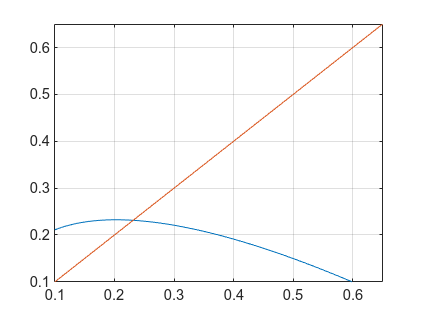

fplot(h(x), intervalo)
ylim(intervalo)
hold on 
grid on
fplot(x,intervalo)


[p, k, err, P] = fixpt (h, 0.5, 1e-2, 100)

p = 0.2316

k = 4

err = 0.0040

P =     0.1496
    0.2276
    0.2316


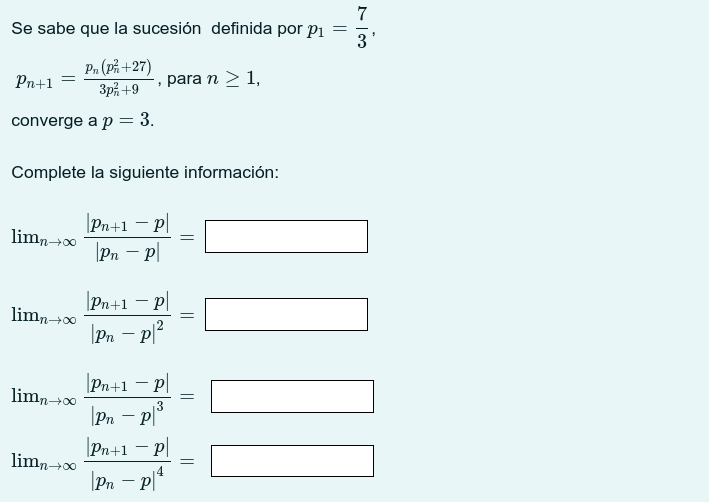

clear
clf
syms x

f(x) = x*(x^2 + 27) / (2*x^2+9)

$$f(x) = \frac{x\,\left(x^{2}+27\right)}{2\,x^{2}+9}$$


p(x) = abs(f(x) - 3)/abs((f(x)-3)^4)

$$p(x) = \frac{1}{{\left|\frac{x\,\left(x^{2}+27\right)}{2\,x^{2}+9}-3\right|}^{3}}$$

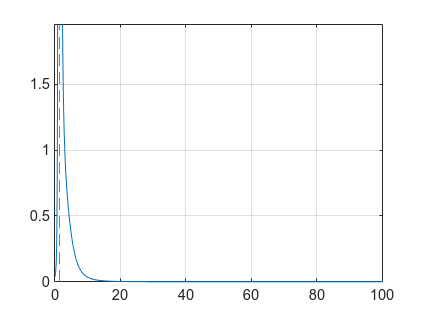


fplot(p, [0 100]) 
grid on


p = matlabFunction(f)

p = function_handle with value:
    @(x)(x.*(x.^2+2.7e+1))./(x.^2.*2.0+9.0)



[p, k, err, P] = fixpt (p, 7/3, 10e-10, 100)

p = 4.2426

k = 15

err = 1.3682e-09

P =     3.8063
    4.1583
    4.2259
    4.2393
    4.2420
    4.2425
    4.2426
    4.2426
    4.2426
    4.2426


clear 
clf
syms h(x)

h(x) = (atan(x)+exp(-x))*sin(2*x) - 1/10*exp(-x)

$$h(x) = \sin\left(2\,x\right)\,\left({\mathrm{e}}^{-x}+\mathrm{atan}\left(x\right)\right)-\frac{{\mathrm{e}}^{-x}}{10}$$

h = matlabFunction(h(x))

h = function_handle with value:
    @(x)exp(-x).*(-1.0./1.0e+1)+sin(x.*2.0).*(exp(-x)+atan(x))


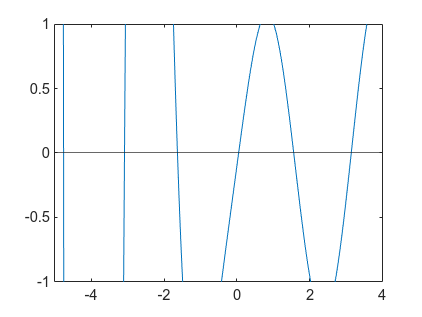


fplot(h,[-5 4])
yline (0)
ylim([-1 1])


[c, err, yc] = bisect (h, -5, -4, 1e-8)

c = -4.7631

err = 7.4506e-09

yc = -1.7193e-07